% demo for embeding
a1=256*256*8

a1 = 524288

a2=512*512*8

a2 = 2097152

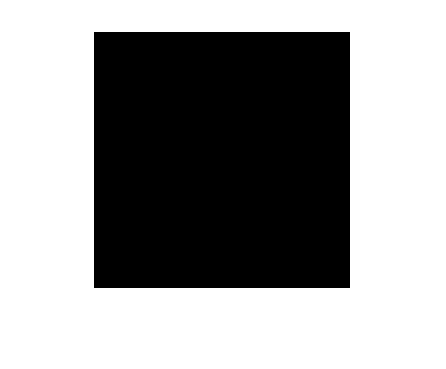

% 嵌入比特的1/4
% 如何利用LBP呢，我感觉无需强硬附和，怎样效果好就怎样来，不要给自己设限
% 或者不去实现
I=uint8(zeros(256));
imshow(I)

I1=imnoise(I,'salt & pepper',0.001);
m1=26

m1 = 26

dec2bin(m1,8)

ans = '00011010'

d1=[125,139,156,158]

d1 =    125   139   156   158


dec2bin(d1) 

ans = 4×8 char 数组
    '01111101'
    '10001011'
    '10011100'
    '10011110'


d2=d1;
for i=1:4
    d2(i)=bitset(d1(i),1,bitget(m1,2*i-1));
    d2(i)=bitset(d2(i),2,bitget(m1,2*i));
end
d2

d2 =    126   138   157   156


dec2bin(d2)

ans = 4×8 char 数组
    '01111110'
    '10001010'
    '10011101'
    '10011100'


m2=0;
for i=1:4
   m2=bitset(m2,2*i-1,bitget(d2(i),1));
   m2=bitset(m2,2*i,bitget(d2(i),2));
end
m2

m2 = 26

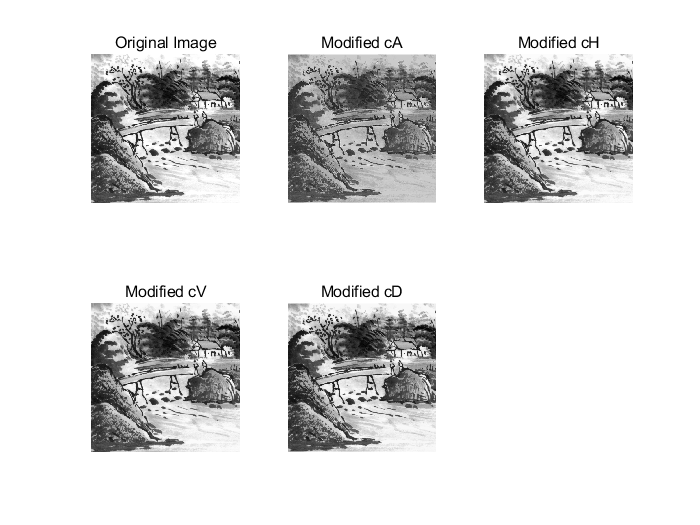

% 读取图像
I = imread("C:\Users\Liushoukang\Desktop\VMIE\image\bridge512.bmp");  % 如果是彩色图像，先转换为灰度图像


% 进行二维小波变换
[cA, cH, cV, cD] = IWT(I);

% 修改各个子带
cA_mod = cA * 0.5;  % 修改 cA
cH_mod = cH * 0.5;  % 修改 cH
cV_mod = cV * 0.5;  % 修改 cV
cD_mod = cD * 0.5;  % 修改 cD

% 逆变换，重构图像
I_reconstructed_cA = IIWT(cA_mod, cH, cV, cD);
I_reconstructed_cH = IIWT(cA, cH_mod, cV, cD);
I_reconstructed_cV = IIWT(cA, cH, cV_mod, cD);
I_reconstructed_cD = IIWT(cA, cH, cV, cD_mod);

% 显示原始图像和重构图像
figure;
subplot(2, 3, 1); imshow(I, []); title('Original Image');
subplot(2, 3, 2); imshow(I_reconstructed_cA, []); title('Modified cA');
subplot(2, 3, 3); imshow(I_reconstructed_cH, []); title('Modified cH');
subplot(2, 3, 4); imshow(I_reconstructed_cV, []); title('Modified cV');
subplot(2, 3, 5); imshow(I_reconstructed_cD, []); title('Modified cD');

% 计算 SSIM 和 PSNR
[ssim_cA, ssim_map_cA] = ssim(uint8(I_reconstructed_cA), I);
psnr_cA = psnr(uint8(I_reconstructed_cA), I);

[ssim_cH, ssim_map_cH] = ssim(uint8(I_reconstructed_cH), I);
psnr_cH = psnr(uint8(I_reconstructed_cH), I);

[ssim_cV, ssim_map_cV] = ssim(uint8(I_reconstructed_cV), I);
psnr_cV = psnr(uint8(I_reconstructed_cV), I);

[ssim_cD, ssim_map_cD] = ssim(uint8(I_reconstructed_cD), I);
psnr_cD = psnr(uint8(I_reconstructed_cD), I);

% 显示 SSIM 和 PSNR
fprintf('SSIM and PSNR results:\n');

SSIM and PSNR results:


fprintf('Modified cA: SSIM = %.4f, PSNR = %.4f dB\n', ssim_cA, psnr_cA);

Modified cA: SSIM = 0.7235, PSNR = 8.9675 dB


fprintf('Modified cH: SSIM = %.4f, PSNR = %.4f dB\n', ssim_cH, psnr_cH);

Modified cH: SSIM = 0.9890, PSNR = 37.6020 dB


fprintf('Modified cV: SSIM = %.4f, PSNR = %.4f dB\n', ssim_cV, psnr_cV);

Modified cV: SSIM = 0.9841, PSNR = 36.1635 dB


fprintf('Modified cD: SSIM = %.4f, PSNR = %.4f dB\n', ssim_cD, psnr_cD);

Modified cD: SSIM = 0.9960, PSNR = 44.2885 dB


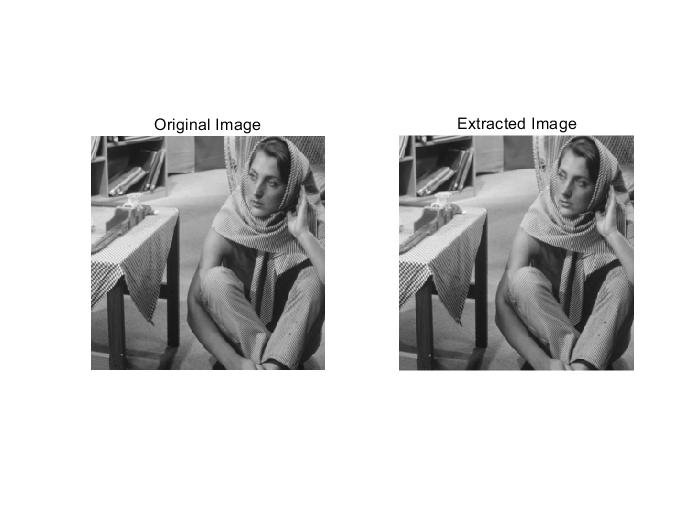

% 读取并灰度化图像
A = imread("C:\Users\Liushoukang\Desktop\VMIE\image\barbara256.bmp");

% 将图像A转化为二进制
A_bin = de2bi(A, 8, 'left-msb');
A_bin = reshape(A_bin, [], 1);

% 生成cH, cV, cD
[cA, cH, cV, cD] = IWT(I);
cH=cH+128;
cV=cV+128;
cD=cD+128;

% 嵌入A_bin到cH, cV, cD
for i = 1:256*256
        % 嵌入前3位到cH的最低3位
        cH(i) = bitset(cH(i), 1, A_bin((i-1)*3+1));
        cH(i) = bitset(cH(i), 2, A_bin((i-1)*3+2));
        cH(i) = bitset(cH(i), 3, A_bin((i-1)*3+3));
end
for j = 1:256*256
        % 嵌入中3位到cV的最低3位
        cV(j) = bitset(cV(j), 1, A_bin((j-1)*3+256*256*3+1));
        cV(j) = bitset(cV(j), 2, A_bin((j-1)*3+256*256*3+2));
        cV(j) = bitset(cV(j), 3, A_bin((j-1)*3+256*256*3+3));
end
for k = 1:256*256
        % 嵌入后2位到cD的最低2位
        cD(k) = bitset(cD(k), 1, A_bin((k-1)*2+256*256*6+1));
        cD(k) = bitset(cD(k), 2, A_bin((k-1)*2+256*256*6+2));
end

% 提取嵌入信息
A_bin_extracted = zeros(256*256*8, 1);


for i = 1:256*256
        A_bin_extracted((i-1)*3+1) = bitget(cH(i), 1);
        A_bin_extracted((i-1)*3+2) = bitget(cH(i), 2);
        A_bin_extracted((i-1)*3+3) = bitget(cH(i), 3);
end
for j = 1:256*256
        % 提取cV的最低3位
        A_bin_extracted((j-1)*3+256*256*3+1) = bitget(cV(j), 1);
        A_bin_extracted((j-1)*3+256*256*3+2) = bitget(cV(j), 2);
        A_bin_extracted((j-1)*3+256*256*3+3) = bitget(cV(j), 3);
end
for k = 1:256*256
        % 提取cD的最低2位
        A_bin_extracted((k-1)*2+256*256*6+1) = bitget(cD(k), 1);
        A_bin_extracted((k-1)*2+256*256*6+2) = bitget(cD(k), 2);
end
A_extracted = reshape(A_bin_extracted, [], 8);
A_extracted = uint8(bi2de(A_extracted, 'left-msb'));
A_extracted = reshape(A_extracted, [256 256]);

% 显示原始图像和提取出的图像
figure;
subplot(1, 2, 1); imshow(uint8(A)); title('Original Image');
subplot(1, 2, 2); imshow(uint8(A_extracted)); title('Extracted Image');

X=double(Temp2);

函数或变量 'Temp2' 无法识别。

I11=EmbedofIL2K(X,C);

figure
imshow(uint8(I11));psnr(uint8(I11),uint8(C))
A1=ExtractofIL2K(double(I11));
imshow(A1)
ssim(A1,uint8(X))

t=double(I2);
a=Scramble(Index,t);
a=Diffusion(a,X);
imshow(uint8(a))
b=IDiffusion(a,X);
b=Unscramble(Index,b);
imshow(uint8(b))

% 加密
Temp1=Scramble(Index,Temp);
Temp2=Diffusion(Temp1,X);
imshow(uint8(Temp))

% 嵌入
C1=EmbedofIL(uint8(Temp2),C);

% 提取 
Temp_extract=double(ExtractofIL(C1));

% 解密
Temp_extract1=IDiffusion(Temp_extract,X);
Temp_extract2=Unscramble(Index,Temp_extract1);
imshow(uint8(Temp_extract2))
ssim(uint8(Temp_extract2),uint8(Temp))
MAX(Temp)
MIN(Temp)

% 输入数据（例如测量值）
x = [1, 2, 3, 4, 5];
% 输出数据（例如实际值）
y = [2.1, 4.0, 5.9, 8.2, 9.8];

% 建立设计矩阵
X = [x', ones(length(x), 1)];

% 使用最小二乘法计算校正系数
coefficients = X \ y';

% 提取校正系数
K1 = coefficients(1);
K2 = coefficients(2);

% 显示校正系数
disp(['K1 = ', num2str(K1)]);
disp(['K2 = ', num2str(K2)]);

% 应用校正系数进行校正
x_new = 6;  % 新的输入数据
y_corrected = K1 * x_new + K2;

disp(['Corrected output for x = ', num2str(x_new), ' is y = ', num2str(y_corrected)]);

A=[10,32;34,45];I=[245,234,90,34;250,214,98,56;43,45,67,67;34,56,34,56];
% [B0,B1,B2,B3]=IWT(I)
% 
% B11 = floor(abs(B1)/2^3)*2^3+floor(A/2^5)
% B11  = TK(B11,B1,3)
%         
% B22 = floor(abs(B2)/2^3)*2^3+mod(floor(A/2^2),2^3)
% B22 = TK(B22,B2,3)
%         
% B33 = floor(abs(B3)/2^2)*2^2+mod(A,2^2)
% B33 = TK(B33,B3,2)
% ANS=IIWT(B0,B11,B22,B33)
% [B0,B1,B2,B3]=IWT(ANS)
% A11=mod(abs(B11),2^3)*2^5+mod(abs(B22),2^3)*2^2+mod(abs(B33),2^2)
ANS=EmbedofIL2K(A,I);
A1=ExtractofIL2K(ANS)

I8=imread("C:\Users\Liushoukang\Desktop\VMIE\image\Lena256.bmp");
[cA,cH,cV,cD]=IWT(I8);
MAX(cA)
MIN(cA)
imshow(uint8(cA))
SUM(LBP(double(cA),30))
imshow(uint8(LBP(double(cA),30)))
SUM(LBP(double(cH),30))
imshow(uint8(LBP(double(cH),30)))
SUM(LBP(double(cV),30))

imshow(uint8(LBP(double(cV),30)))
SUM(LBP(double(cD),30))
imshow(uint8(LBP(double(cD),30)))

